## divide train set and test set

data = X_nir_totaled(1:600,:);
label = y_nir;
format short g
% rng(1); % For reproducibility
% cvp = cvpartition(y, 'Holdout', 0.3)

## modified cars 

%vsels = [];
%RMSECVs = [];

testnums = [50, 100, 200, 500];
vsel_best_m1 = zeros(100, length(testnums));
RMSECV_mins1 = zeros(1, length(testnums));
minRMSECVs1 = [];
num_vsel_cars1 = [];

for cc = 1:length(testnums)

    iternum = testnums(cc);
    RMSECV_min = 1;

    for i = 1:iternum
        Cars = feature_cars_ori(data(training(cvp), :),...
            label(training(cvp)), 7, 5, 'center', 100);
        vsel_incre = Cars.vsel;
        minRMSECV_incre = Cars.minRMSECV;
        %RMSECV_incre = Cars.RMSECV;

        %vsels = [vsels, vsel_incre];
        %RMSECVs = [RMSECVs, RMSECV_incre];
        minRMSECVs1 = [minRMSECVs1, minRMSECV_incre];
        num_vsel_cars1 = [num_vsel_cars1, length(vsel_incre)];

        if minRMSECV_incre < RMSECV_min
            RMSECV_min = minRMSECV_incre;
            vsel_best = vsel_incre;
        end
    end
         
    fprintf('The %d try finished.\n', iternum)
    fprintf('RMSECV_min = %.6f \n', RMSECV_min)
    vsel_best
    
    RMSECV_mins1(cc) = RMSECV_min;
    vsel_best_00 = [vsel_best, zeros(1, 100-length(vsel_best))];
    vsel_best_m1(:, cc) = vsel_best_00;
  
    
end

The 50 try finished.


RMSECV_min = 0.403116 


vsel_best =     17    18    22    23    41    42   179   198   233   234   260   303   304   318   319   329


The 100 try finished.


RMSECV_min = 0.399819 


vsel_best =     18    19    21    22    23    41    42   179   198   232   233   234   260   303   304   318   319   329   350


The 200 try finished.


RMSECV_min = 0.398433 


vsel_best =     18    22    23    41    42   179   198   232   234   235   260   304   305   318   319   329   350


The 500 try finished.


RMSECV_min = 0.399332 


vsel_best =     17    18    22    23    24    41   179   198   232   233   235   260   303   305   318   319   329   350


group_cars = [];

for cc = 1:length(testnums)
    group_cars = [group_cars, repmat(testnums(cc), 1, testnums(cc))];
end

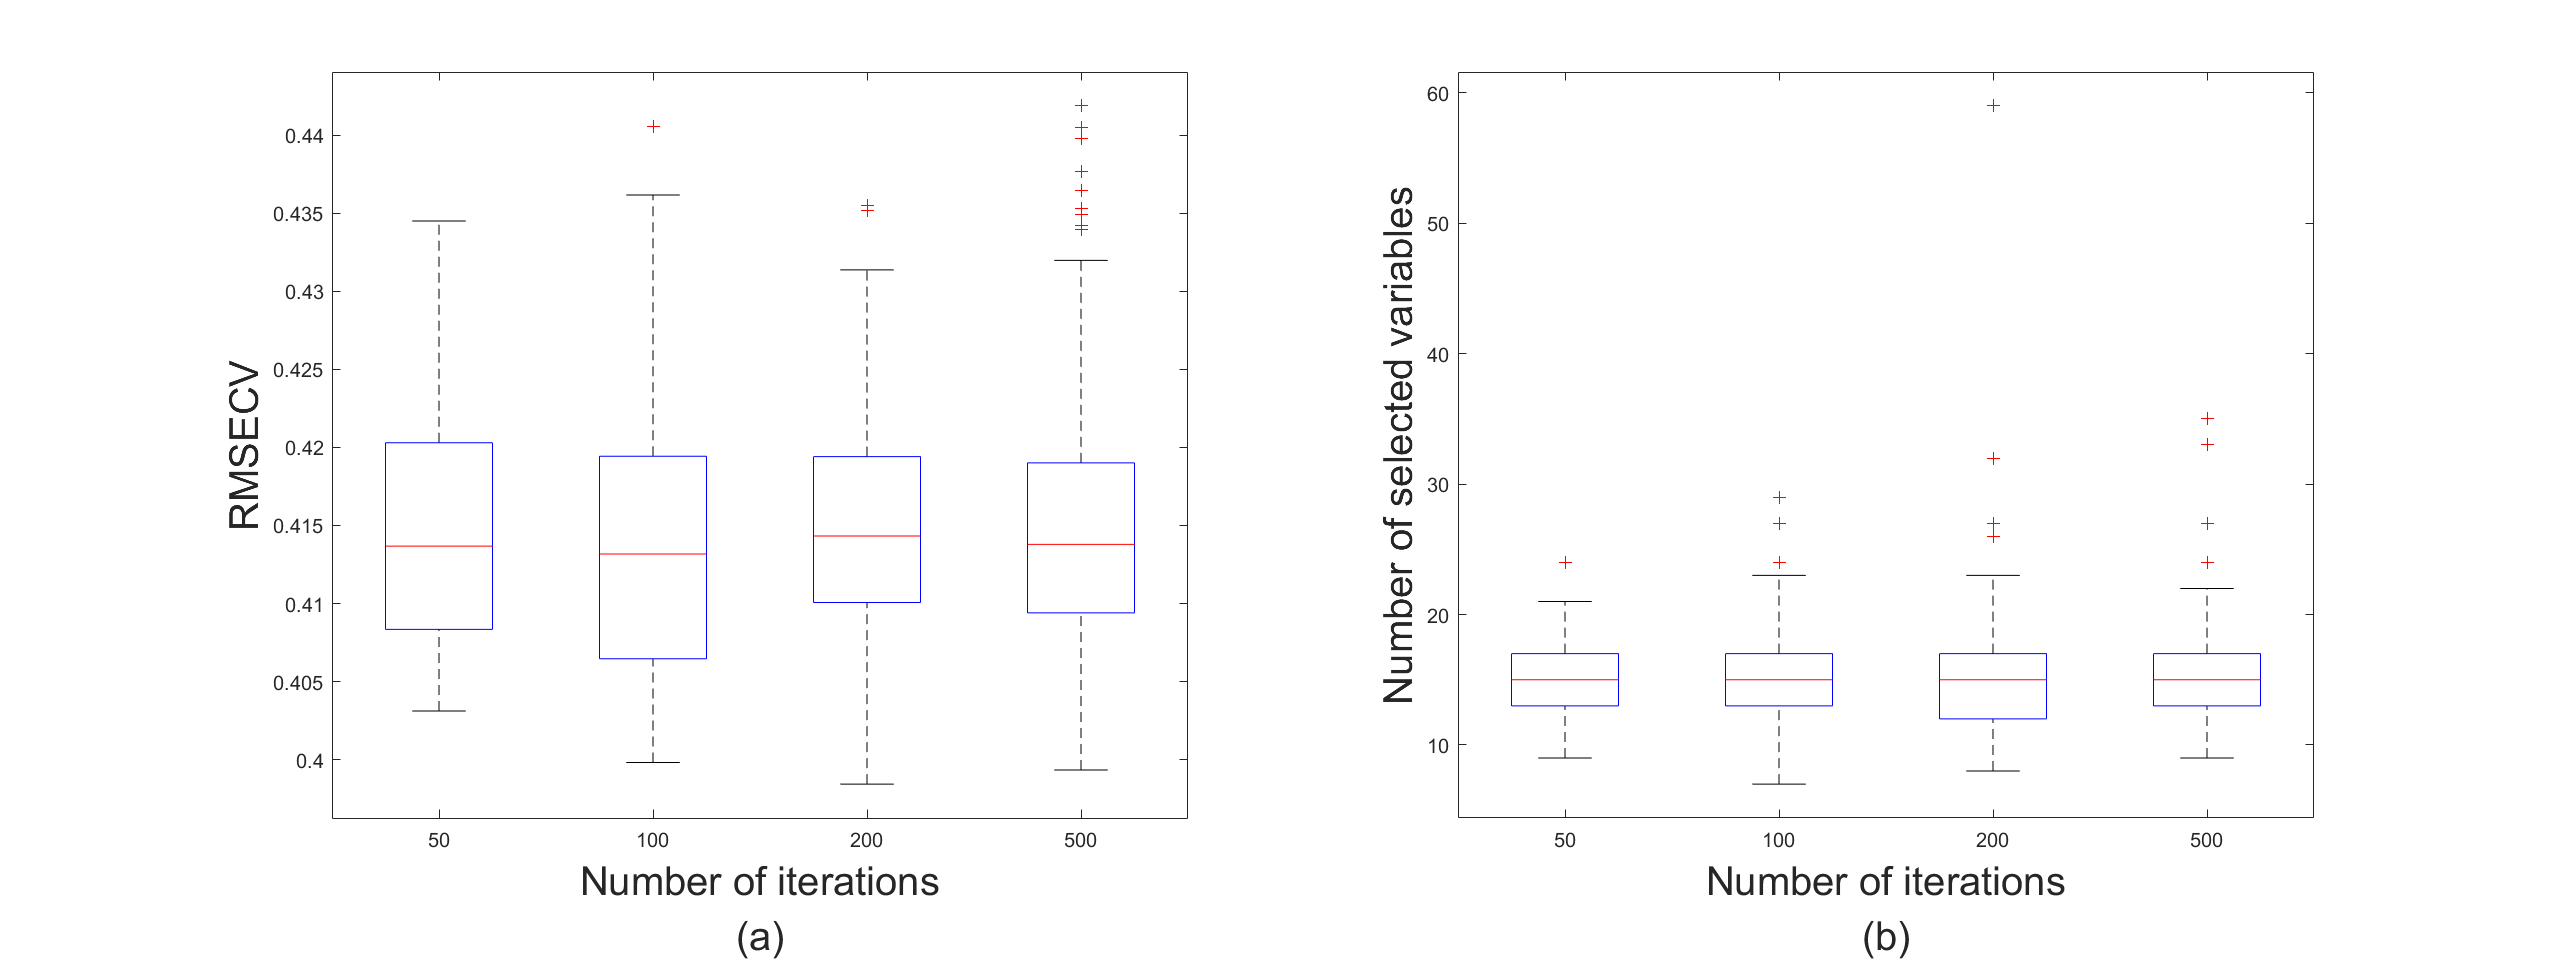

%boxplot of rmse and vsel num
figure('Units','normalized', 'Position', [0, 0, 1, 0.6]);

subplot(1,2,1)
boxplot(minRMSECVs1, group_cars)
xlabel({'Number of iterations', '(a)'}, "FontSize", 20);
ylabel('RMSECV', "FontSize", 20);

subplot(1,2,2)
boxplot(num_vsel_cars1, group_cars)
xlabel({'Number of iterations', '(b)'}, "FontSize", 20);
ylabel('Number of selected variables', "FontSize", 20);

RMSECV_mins1

RMSECV_mins1 =       0.40312      0.39982      0.39843      0.39933


vsel_best_m1

vsel_best_m1 =     17    18    18    17
    18    19    22    18
    22    21    23    22
    23    22    41    23
    41    23    42    24
    42    41   179    41
   179    42   198   179
   198   179   232   198
   233   198   234   232
   234   232   235   233


% effshift(vsel_best)
% RMSECV_min

% freqs = [];
% 
% for j = 1:length(effshift)
%     freq = sum(vsels == j);
%     freqs = [freqs, freq];
% end
% 
% vsel = find(freqs >= floor(iternum * 0.5))
% effshift(vsel)
% 
% CV = plscvfold(data(training(cvp), vsel), label(training(cvp)), 7);  
%    
% CV.RMSE_min
% CV.Rsquare_max     


## vsel_spa

data = X;
label = y;

train_data  = data(training(cvp), vsel_spa);
train_label = label(training(cvp));
test_data   = data(test(cvp), vsel_spa);
test_label  = label(test(cvp));

rng(1); % For reproducibility
randIndex1 = randperm(size(train_data,1));
rng(1); % For reproducibility
randIndex2 = randperm(size(test_data,1));

train_data  = train_data(randIndex1, :);
train_label = train_label(randIndex1);
test_data   = test_data(randIndex2, :);
test_label  = test_label(randIndex2);

*
optimization finished, #iter = 111
nu = 0.017958
obj = -8.195832, rho = 0.186552
nSV = 29, nBSV = 0
*
optimization finished, #iter = 116
nu = 0.035015
obj = -16.236393, rho = -0.017586
nSV = 26, nBSV = 1
*
optimization finished, #iter = 90
nu = 0.016315
obj = -7.447742, rho = -0.150639
nSV = 20, nBSV = 0
*
optimization finished, #iter = 93
nu = 0.034607
obj = -15.795122, rho = -0.347106
nSV = 22, nBSV = 0
*
optimization finished, #iter = 52
nu = 0.016995
obj = -7.757142, rho = -0.299564
nSV = 21, nBSV = 0
*.*
optimization finished, #iter = 217
nu = 0.199172
obj = -121.169669, rho = 0.013358
nSV = 46, nBSV = 24
Total nSV = 105
*
optimization finished, #iter = 106
nu = 0.018063
obj = -8.243809, rho = 0.140004
nSV = 30, nBSV = 0
*
optimization finished, #iter = 117
nu = 0.035548
obj = -16.586675, rho = -0.020195
nSV = 28, nBSV = 1
*
optimization finished, #iter = 101
nu = 0.021571
obj = -9.844868, rho = -0.066870
nSV = 25, nBSV = 0
*
optimization finished, #iter = 101
nu = 0.031717
obj 

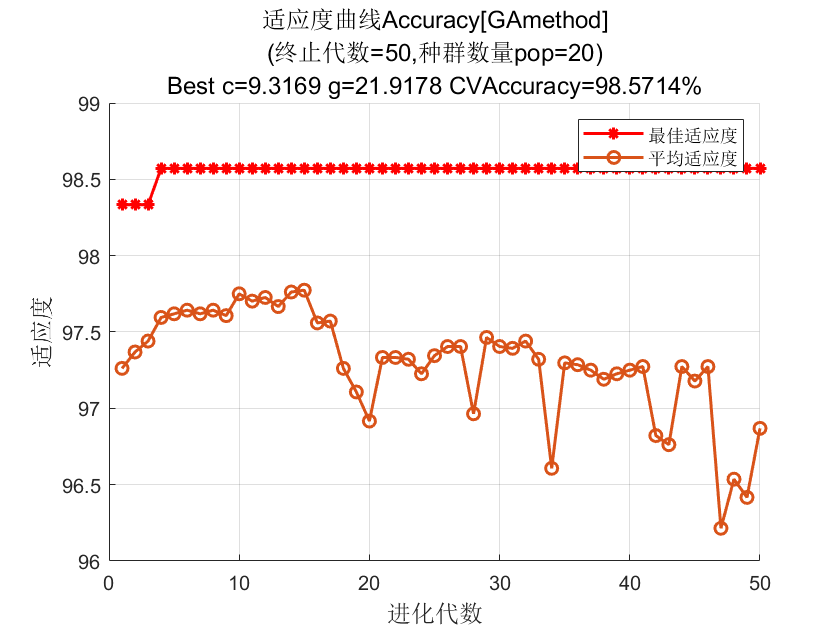

tic
[bestacc, bestc, bestg] = gaSVMcgForClass(train_label, train_data);

toc

历时 24.754580 秒。


s = 0;
t = 2;
c = bestc;
g = bestg;
options = [' -s ',num2str(s),' -t ',num2str(t),' -c ',num2str(c),' -g ',num2str(g)]; 
model = libsvmtrain(train_label, train_data, options); 

*
optimization finished, #iter = 116
nu = 0.012464
obj = -12.196069, rho = 0.449362
nSV = 18, nBSV = 0
*
optimization finished, #iter = 152
nu = 0.030167
obj = -30.592433, rho = -0.038946
nSV = 21, nBSV = 2
*
optimization finished, #iter = 58
nu = 0.016415
obj = -16.677396, rho = -0.126029
nSV = 12, nBSV = 1
*
optimization finished, #iter = 72
nu = 0.031515
obj = -31.801835, rho = -0.572756
nSV = 16, nBSV = 2
*
optimization finished, #iter = 86
nu = 0.014263
obj = -13.952219, rho = -0.426036
nSV = 13, nBSV = 0
*.*
optimization finished, #iter = 237
nu = 0.198531
obj = -267.268372, rho = 0.339215
nSV = 50, nBSV = 32
Total nSV = 105



[train_pred_label, train_acc, ~]...
           = libsvmpredict(train_label, train_data, model);

Accuracy = 99.2857% (417/420) (classification)


[test_pred_label, test_acc, ~]...
           = libsvmpredict(test_label, test_data, model);

Accuracy = 97.7778% (176/180) (classification)


## vsel_best

data = X;
label = y;

train_data  = data(training(cvp), vsel_best);
train_label = label(training(cvp));
test_data   = data(test(cvp), vsel_best);
test_label  = label(test(cvp));

rng(1); % For reproducibility
randIndex1 = randperm(size(train_data,1));
rng(1); % For reproducibility
randIndex2 = randperm(size(test_data,1));

train_data  = train_data(randIndex1, :);
train_label = train_label(randIndex1);
test_data   = test_data(randIndex2, :);
test_label  = test_label(randIndex2);

*
optimization finished, #iter = 48
nu = 0.435235
obj = -45.881631, rho = 0.533643
nSV = 76, nBSV = 72
*
optimization finished, #iter = 41
nu = 0.429022
obj = -54.490630, rho = 0.134192
nSV = 74, nBSV = 71
*
optimization finished, #iter = 20
nu = 0.214951
obj = -23.471783, rho = 0.111692
nSV = 38, nBSV = 36
*
optimization finished, #iter = 70
nu = 0.623336
obj = -79.881098, rho = -0.472801
nSV = 106, nBSV = 102
*
optimization finished, #iter = 44
nu = 0.286259
obj = -32.263252, rho = -0.438462
nSV = 50, nBSV = 47
*
optimization finished, #iter = 57
nu = 0.629220
obj = -80.561873, rho = 0.026967
nSV = 107, nBSV = 104
Total nSV = 242
*
optimization finished, #iter = 54
nu = 0.448450
obj = -46.943451, rho = 0.109770
nSV = 78, nBSV = 71
*
optimization finished, #iter = 42
nu = 0.464577
obj = -58.401025, rho = 0.225448
nSV = 80, nBSV = 78
*
optimization finished, #iter = 23
nu = 0.261905
obj = -29.265553, rho = 0.277034
nSV = 44, nBSV = 44
*
optimization finished, #iter = 57
nu = 0.590036
o

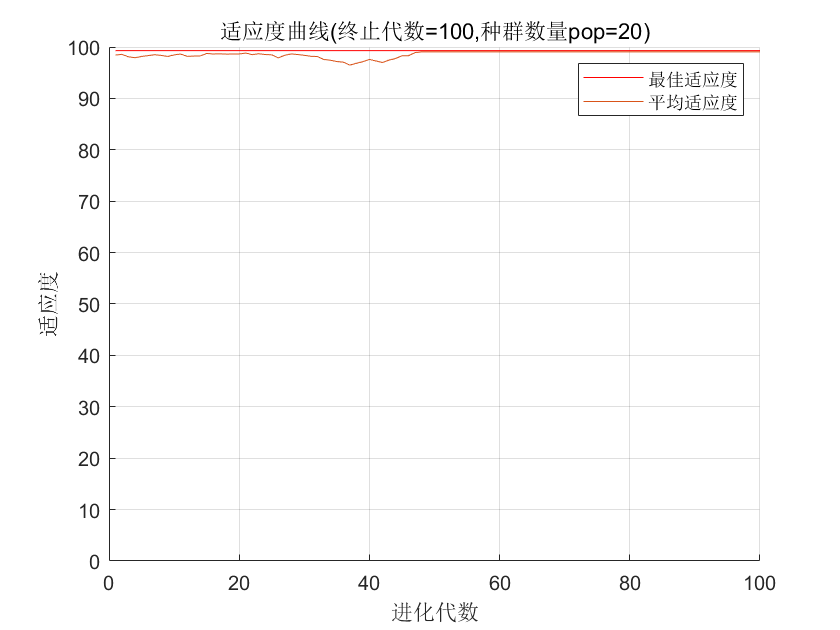

tic
[bestacc, bestc, bestg] = gaSVMcgForClass2009(train_label, train_data);

toc

历时 46.376346 秒。


% vsel_best
s = 0;
t = 2;
c = bestc;
g = bestg;
options = [' -s ',num2str(s),' -t ',num2str(t),' -c ',num2str(c),' -g ',num2str(g)]; 
model = libsvmtrain(train_label, train_data, options); 

*
optimization finished, #iter = 89
nu = 0.013762
obj = -12.472245, rho = 0.275327
nSV = 22, nBSV = 0
*.*
optimization finished, #iter = 243
nu = 0.029271
obj = -30.079860, rho = -0.300908
nSV = 23, nBSV = 3
*
optimization finished, #iter = 58
nu = 0.012346
obj = -11.189870, rho = -0.121873
nSV = 14, nBSV = 0
*.*
optimization finished, #iter = 312
nu = 0.049352
obj = -44.816972, rho = -0.202085
nSV = 32, nBSV = 1
*
optimization finished, #iter = 81
nu = 0.015350
obj = -13.912129, rho = -0.343010
nSV = 18, nBSV = 0
*
optimization finished, #iter = 129
nu = 0.089201
obj = -113.795580, rho = 1.053266
nSV = 31, nBSV = 14
Total nSV = 94



[train_pred_label, train_acc, ~]...
           = libsvmpredict(train_label, train_data, model);

Accuracy = 99.5238% (418/420) (classification)


[test_pred_label, test_acc, ~]...
           = libsvmpredict(test_label, test_data, model);

Accuracy = 100% (180/180) (classification)


## vsel

data = X;
label = y;

train_data  = data(training(cvp), vsel);
train_label = label(training(cvp));
test_data   = data(test(cvp), vsel);
test_label  = label(test(cvp));

rng(1); % For reproducibility
randIndex1 = randperm(size(train_data,1));
rng(1); % For reproducibility
randIndex2 = randperm(size(test_data,1));

train_data  = train_data(randIndex1, :);
train_label = train_label(randIndex1);
test_data   = test_data(randIndex2, :);
test_label  = test_label(randIndex2);

*
optimization finished, #iter = 94
nu = 0.028472
obj = -12.993708, rho = 0.161775
nSV = 16, nBSV = 0
*
optimization finished, #iter = 68
nu = 0.055968
obj = -28.894621, rho = -0.415324
nSV = 19, nBSV = 7
*
optimization finished, #iter = 39
nu = 0.016171
obj = -7.539149, rho = -0.302165
nSV = 10, nBSV = 1
*
optimization finished, #iter = 118
nu = 0.144168
obj = -82.361668, rho = -0.135497
nSV = 33, nBSV = 18
*
optimization finished, #iter = 29
nu = 0.026550
obj = -13.900046, rho = -0.535541
nSV = 12, nBSV = 4
*
optimization finished, #iter = 90
nu = 0.128564
obj = -81.335723, rho = 0.726005
nSV = 28, nBSV = 17
Total nSV = 85
*
optimization finished, #iter = 69
nu = 0.031517
obj = -14.608921, rho = 0.105422
nSV = 19, nBSV = 2
*
optimization finished, #iter = 120
nu = 0.061252
obj = -32.327525, rho = -0.371383
nSV = 20, nBSV = 6
*
optimization finished, #iter = 61
nu = 0.027627
obj = -12.608303, rho = -0.110345
nSV = 13, nBSV = 0
*
optimization finished, #iter = 155
nu = 0.137455
obj = -

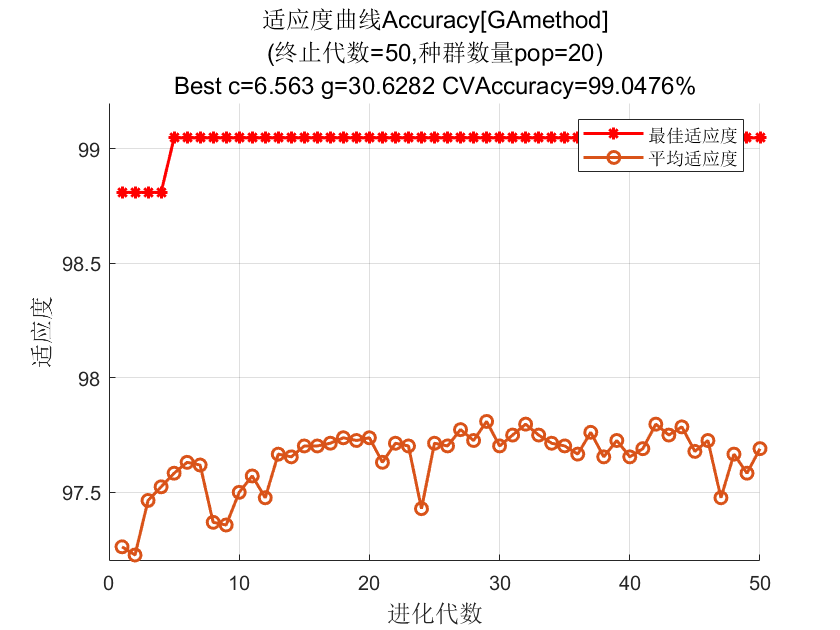

tic
[bestacc, bestc, bestg] = gaSVMcgForClass(train_label, train_data);

toc

历时 20.655461 秒。


% vsel
s = 0;
t = 2;
c = bestc;
g = bestg;
options = [' -s ',num2str(s),' -t ',num2str(t),' -c ',num2str(c),' -g ',num2str(g)]; 
model = libsvmtrain(train_label, train_data, options); 

*
optimization finished, #iter = 59
nu = 0.030410
obj = -21.905967, rho = 0.266639
nSV = 14, nBSV = 3
*
optimization finished, #iter = 92
nu = 0.062952
obj = -49.710301, rho = -0.341314
nSV = 19, nBSV = 10
*
optimization finished, #iter = 52
nu = 0.027230
obj = -19.321020, rho = 0.002561
nSV = 12, nBSV = 3
*
optimization finished, #iter = 154
nu = 0.147669
obj = -129.468989, rho = -0.215349
nSV = 39, nBSV = 25
*
optimization finished, #iter = 145
nu = 0.034182
obj = -28.036135, rho = -0.276708
nSV = 19, nBSV = 4
*
optimization finished, #iter = 50
nu = 0.142390
obj = -137.089830, rho = 1.359006
nSV = 33, nBSV = 27
Total nSV = 101


[train_pred_label, train_acc, ~]...
           = libsvmpredict(train_label, train_data, model);

Accuracy = 99.2857% (417/420) (classification)


[test_pred_label, test_acc, ~]...
           = libsvmpredict(test_label, test_data, model);

Accuracy = 99.4444% (179/180) (classification)


## confusion matrix

% plotconfusion(test_label.', test_pred_label.');

# model = libsvmtrain(label, data, ‘option’)

# [predicted_label, accuracy,decision_values] = libsvmpredict(y_test, x_test, model)

% options:
% -s svm_type : set type of SVM (default 0)
% 	0 -- C-SVC		(multi-class classification)
% 	1 -- nu-SVC		(multi-class classification)
% 	2 -- one-class SVM
% 	3 -- epsilon-SVR	(regression)
% 	4 -- nu-SVR		(regression)
% -t kernel_type : set type of kernel function (default 2)
% 	0 -- linear: u'*v
% 	1 -- polynomial: (gamma*u'*v + coef0)^degree
% 	2 -- radial basis function: exp(-gamma*|u-v|^2)
% 	3 -- sigmoid: tanh(gamma*u'*v + coef0)
% 	4 -- precomputed kernel (kernel values in training_set_file)
% -d degree : set degree in kernel function (default 3)
% -g gamma : set gamma in kernel function (default 1/num_features)  
%            gamma越大，支持向量越少，过拟合
% -r coef0 : set coef0 in kernel function (default 0)
% -c cost : set the parameter C of C-SVC, epsilon-SVR, and nu-SVR (default 1)
%           C是惩罚系数（正则化参数的倒数），即对误差的宽容度，c越大，容易过拟合
% -n nu : set the parameter nu of nu-SVC, one-class SVM, and nu-SVR (default 0.5)
% -p epsilon : set the epsilon in loss function of epsilon-SVR (default 0.1)
% -m cachesize : set cache memory size in MB (default 100)
% -e epsilon : set tolerance of termination criterion (default 0.001)
% -h shrinking : whether to use the shrinking heuristics, 0 or 1 (default 1)
% -b probability_estimates : whether to train a SVC or SVR model for probability estimates, 0 or 1 (default 0)
% -wi weight : set the parameter C of class i to weight*C, for C-SVC (default 1)
% -v n: n-fold cross validation mode(default 5)
% -q : quiet mode (no outputs)

% iter为迭代次数，
% nu 与前面的操作参数-n nu 相同，
% obj为SVM文件转换为的二次规划求解得到的最小值，
% rho 为判决函数的常数项b，
% nSV 为支持向量个数，
% nBSV为边界上的支持向量个数，
% Total nSV为支持向量总个数。
% 训练后的模型保存为文件*.model，用记事本打开其内容如下：
% svm_type c_svc % 训练所采用的svm类型，此处为C- SVC
% kernel_type rbf %训练采用的核函数类型，此处为RBF核
% gamma 0.0769231 %设置核函数中的g ，默认值为1/ k
% nr_class 2 %分类时的类别数，此处为两分类问题
% total_sv 132 %总共的支持向量个数
% rho 0.424462 %决策函数中的常数项b
% label 1 -1%类别标签
% nr_sv 64 68 %各类别标签对应的支持向量个数